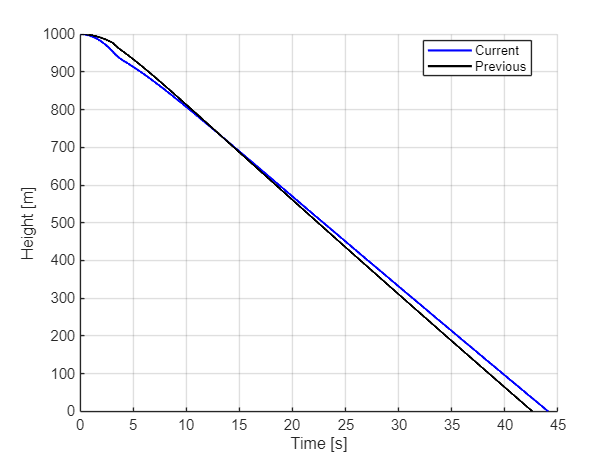

clc
clear 
close all

% Carregar dados
out = load("sim_joao_v4.mat").out;
load("sim_mod_prev.mat")

% Criar pasta se não existir
if ~exist('./img', 'dir')
    mkdir('./img');
end

%% Comparação da Altura
fig1 = figure();
hold on
plot(out.main_clock, out.vehicle_position(:, 3), 'b', 'LineWidth', 1.5, 'DisplayName', 'Current')
plot(t_final, h_final, 'k', 'LineWidth', 1.5, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
ylabel('Height [m]')
ylim([0 1000])
legend("Location","best")
hold off
exportgraphics(fig1, './img/height_comparison.eps')

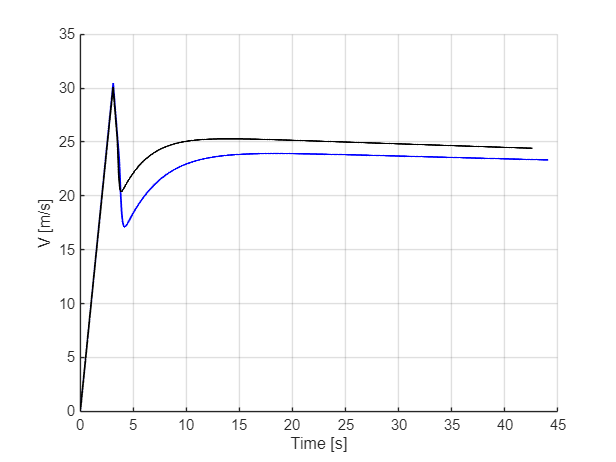


%% Velocidade - Completa
fig2 = figure();
hold on
plot(out.main_clock, -out.vehicle_velocity(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, v_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
ylabel('V [m/s]')
% legend("Location","best")
hold off
exportgraphics(fig2, './img/velocity_comparison_full.eps')

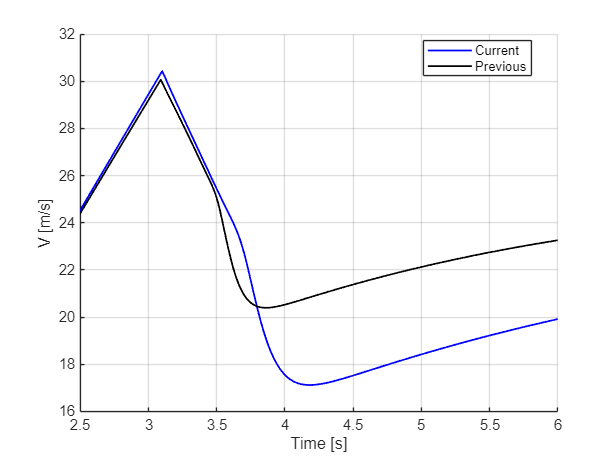


%% Velocidade - Zoom
fig3 = figure();
hold on
plot(out.main_clock, -out.vehicle_velocity(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, v_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
xlim([2.5 6])
ylabel('V [m/s]')
legend("Location","best")
hold off
exportgraphics(fig3, './img/velocity_comparisonoom.eps')

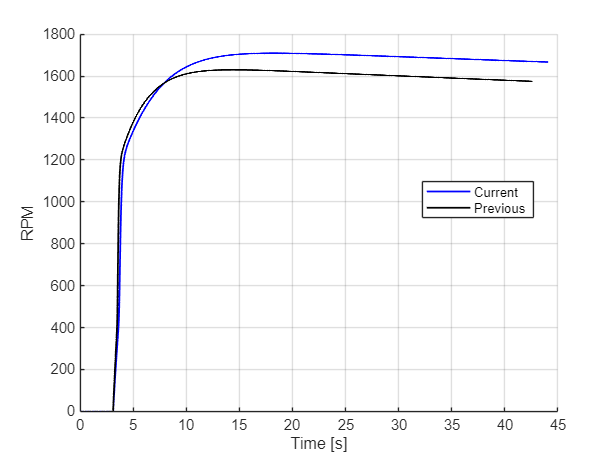


%% RPM
fig4 = figure();
hold on
plot(out.main_clock, out.rotor_rpm, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, RPM, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
ylabel('RPM')
legend("Location","best")
hold off
exportgraphics(fig4, './img/rpm_comparison.eps')

## Força no Rotor

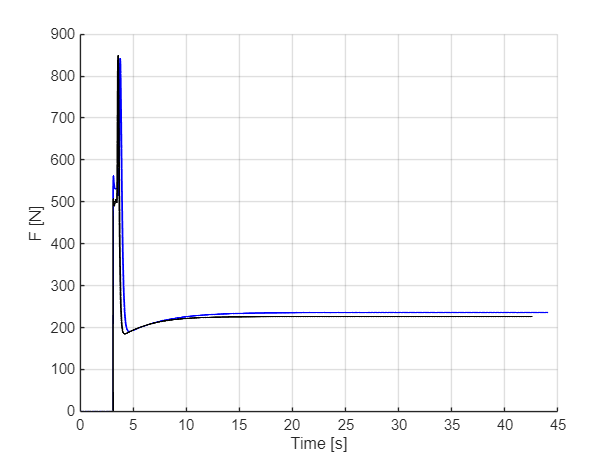

fig5 = figure();
hold on
plot(out.main_clock, out.F_rotor(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, thrust_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
ylabel('F [N]')
% legend("Location","best")
hold off
exportgraphics(fig5, './img/thrust_comparison_full.eps')

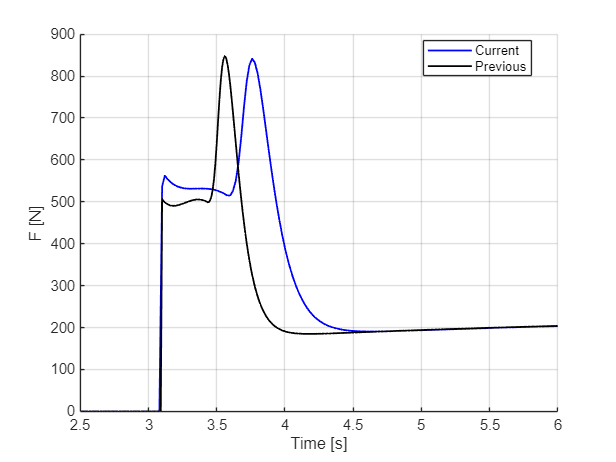


fig5 = figure();
hold on
plot(out.main_clock, out.F_rotor(:, 3), 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, thrust_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
xlim([2.5 6])
ylabel('F [N]')
legend("Location","best")
hold off
exportgraphics(fig5, './img/thrust_comparison.eps')

## Torque no Rotor

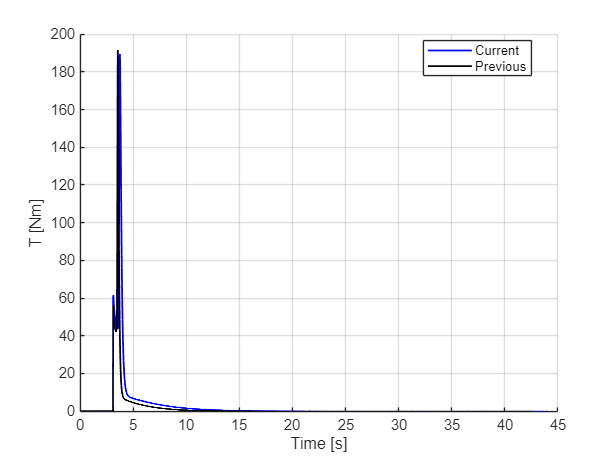

fig6 = figure();
hold on
plot(out.main_clock, out.T_rotor, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, torque_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
ylabel('T [Nm]')
legend("Location","best")
hold off
exportgraphics(fig6, './img/torque_comparison_full.eps')

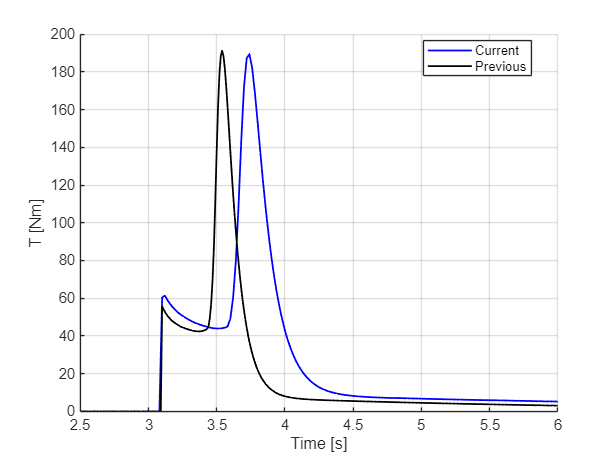


fig6 = figure();
hold on
plot(out.main_clock, out.T_rotor, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t_final, torque_final, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
xlim([2.5 6])
ylabel('T [Nm]')
legend("Location","best")
hold off
exportgraphics(fig6, './img/torque_comparisonoom.eps')

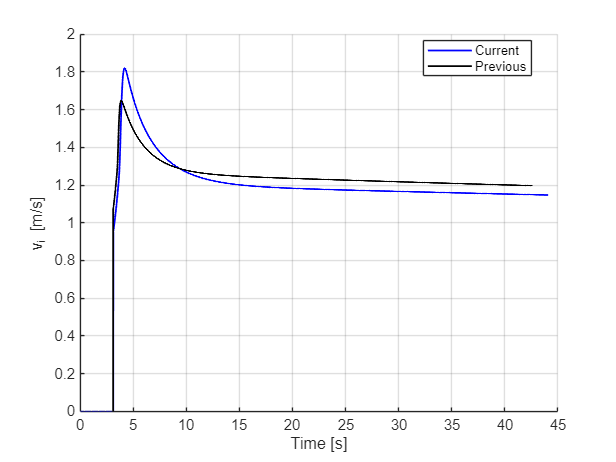


%% Velocidade Induzida - Completa
fig7 = figure();
hold on
plot(out.main_clock, out.rotor_induced_velocity, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t, vi_vec, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
ylabel('v_i [m/s]')
legend("Location","best")
hold off
exportgraphics(fig7, './img/vi_comparison_full.eps')

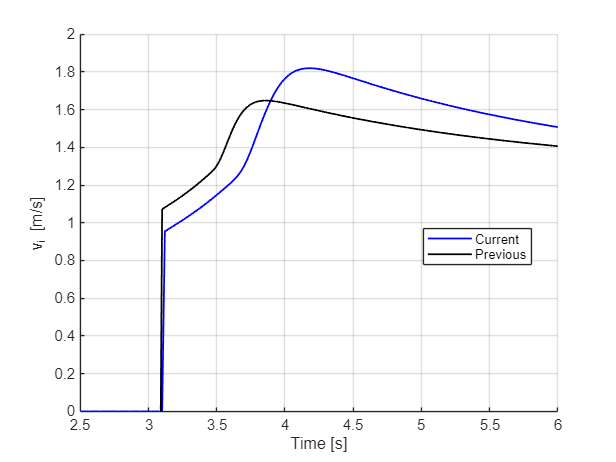


%% Velocidade Induzida - Zoom
fig8 = figure();
hold on
plot(out.main_clock, out.rotor_induced_velocity, 'b', 'LineWidth', 1.2, 'DisplayName', 'Current')
plot(t, vi_vec, 'k', 'LineWidth', 1.2, 'DisplayName', 'Previous')
grid on
xlabel('Time [s]')
xlim([2.5 6])
ylabel('v_i [m/s]')
legend("Location","best")
hold off
exportgraphics(fig8, './img/vi_comparisonoom.eps')